clc
clear
close all

% 平面极坐标机器人
% theta         d              a           alpha
theta1 = 0.0;   d1 = 0.0;      a1 = 0.0;   alpha1 = pi/2;
theta2 = 0.0;   d2 = 0.0;      a2 = 0.0;   alpha2 = 0;

Lr = Link('d', d1, 'a', a1, 'alpha', alpha1, 'revolute');
Lp = Link('prismatic', 'theta', theta2, 'a', a2, 'alpha', alpha2, 'qlim',[0.5,3]);
robot = SerialLink([Lr Lp], 'name', 'RP\_bot')

 
robot = 
 
RP\_bot:: 2 axis, RP, stdDH, slowRNE                             
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          0|     1.5708|          0|
|  2|          0|         q2|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 



% 指定关节变量
q1 = 50; q1 = q1*pi/180;     % 第一个回转关节的回转角度
q2 = 2;                     % 第二个移动关节的移动距离
q = [q1, q2];

% 显示机器人，并看到关节的构型
view([45.0 45.0]); 
plotvol([-2.50 2.5 -2.5 2.5 -1.0 1.5]);
robot.plot(q);

% 拷贝下面命令到命令行窗口，会得到一个更好的现实，因为是用的RTB的命令。
%robot.teach;

% 用Fkine求正运动学，即获得坐标变换矩阵
T = robot.fkine(q)

% 根据D-H法则，手动计算的坐标变换矩阵
theta1 = q(1); 
T01A = transl(0,0,d1)*trotz(theta1);
T01B = transl(a1,0,0)*trotx(alpha1);
T01 = T01A * T01B;

d2 = q(2);
T12A = transl(0,0,d2)*trotz(theta2);
T12B = transl(a2,0,0)*trotx(alpha2);
T12 = T12A * T12B;

T02 = T01*T12
% 通过q1和q2的控件，可以改变机器人的关节变量的数值。
% 注意观察T和T02的数值，可能会存在一些计算精度造成的

clc
clear
close all

% 平面三连杆机械臂
% theta         d             a           alpha
theta1 = 0.0;   d1 = 0.0;     a1 = 1.0;   alpha1 = 0;
theta2 = 0.0;   d2 = 0.0;     a2 = 1.0;   alpha2 = 0;
theta3 = 0.0;   d3 = 0.0;     a3 = 1.0;   alpha3 = 0;

Lr1 = Link('revolute', 'd', d1, 'a', a1, 'alpha', alpha1, 'qlim',[-pi,pi]);
Lr2 = Link('revolute', 'd', d2, 'a', a2, 'alpha', alpha2, 'qlim',[-pi,pi]);
Lr3 = Link('revolute', 'd', d3, 'a', a3, 'alpha', alpha3, 'qlim',[-pi,pi]);
robot = SerialLink([Lr1 Lr2 Lr3], 'name', 'RRR\_Bot')

% 指定关节变量
q1 = -15; q1 = q1*pi/180;     % 第一个关节的回转角度
q2 = 45; q2 = q2*pi/180;     % 第二个关节的回转角度
q3 = -90; q3 = q3*pi/180;     % 第三个关节的回转角度
q = [q1, q2, q3];

view([50.0 70.0]); 
plotvol([-2.0 3.0 -2.5 3.0 -1.0 1.5]);
robot.plot(q);

% 拷贝下面命令到命令行窗口，会得到一个更好的现实，因为是用的RTB的命令。
%robot.teach;

% 用Fkine求正运动学，即获得坐标变换矩阵
T = robot.fkine(q)

% 根据D-H法则，手动计算的坐标变换矩阵
theta1 = q(1); 
T01A = transl(0,0,d1)*trotz(theta1);
T01B = transl(a1,0,0)*trotx(alpha1);
T01 = T01A * T01B;

theta2 = q(2);
T12A = transl(0,0,d2)*trotz(theta2);
T12B = transl(a2,0,0)*trotx(alpha2);
T12 = T12A * T12B;

theta3 = q(3);
T23A = transl(0,0,d3)*trotz(theta3);
T23B = transl(a3,0,0)*trotx(alpha3);
T23 = T23A * T23B;

T03 = T01*T12*T23
% 通过q1，q2和q3的控件，可以改变机器人的关节变量的数值。

clc
clear
close all


% 拟人肩关节
% theta         d             a           alpha
theta1 = 0.0;   d1 = 0.0;     a1 = 0.0;   alpha1 = pi/2;
theta2 = 0.0;   d2 = 0.0;     a2 = 1.0;   alpha2 = 0;
theta3 = 0.0;   d3 = 0.0;     a3 = 1.0;   alpha3 = 0;

Lr1 = Link('revolute', 'd', d1, 'a', a1, 'alpha', alpha1, 'qlim',[-pi,pi]);
Lr2 = Link('revolute', 'd', d2, 'a', a2, 'alpha', alpha2, 'qlim',[-pi,pi]);
Lr3 = Link('revolute', 'd', d3, 'a', a3, 'alpha', alpha3, 'qlim',[-pi,pi]);
robot = SerialLink([Lr1 Lr2 Lr3], 'name', 'RRR\_Shoulder')

% 指定关节变量
q1 = 15; q1 = q1*pi/180;     % 第一个关节的回转角度
q2 = 70; q2 = q2*pi/180;     % 第二个关节的回转角度
q3 = 0; q3 = q3*pi/180;     % 第三个关节的回转角度
q = [q1, q2, q3];

view([20.0 70.0]); 
plotvol([-2.0 3.0 -2.5 3.0 -1.0 2.5]);
robot.plot(q);

% 命令行显示
%robot.teach;

clc
clear
close all


% 创建球形腕
% theta         d             a           alpha
theta1 = 0.0;   d1 = 0.0;     a1 = 0.0;   alpha1 = -pi/2;
theta2 = 0.0;   d2 = 0.0;     a2 = 0.0;   alpha2 = pi/2;
theta3 = 0.0;   d3 = 0.5;     a3 = 0.0;   alpha3 = 0;

Lr1 = Link('revolute', 'd', d1, 'a', a1, 'alpha', alpha1, 'qlim',[-pi,pi]);
Lr2 = Link('revolute', 'd', d2, 'a', a2, 'alpha', alpha2, 'qlim',[-pi,pi]);
Lr3 = Link('revolute', 'd', d3, 'a', a3, 'alpha', alpha3, 'qlim',[-pi,pi]);
robot = SerialLink([Lr1 Lr2 Lr3], 'name', 'RRR\_Wrist')

% 指定关节变量
q1 = 0; q1 = q1*pi/180;     % 第一个关节的回转角度
q2 = 45; q2 = q2*pi/180;     % 第二个关节的回转角度
q3 = 25; q3 = q3*pi/180;     % 第三个关节的回转角度
q = [q1, q2, q3];

view([20.0 70.0]); 
plotvol([-1.0 1.0 -1.0 1.0 -0.5 2.0]);
robot.plot(q);

% 命令行显示
%robot.teach;

clc
clear
close all

% 斯坦福机器人
% theta         d             a           alpha
theta1 = 0.0;   d1 = 0.412;   a1 = 0.0;   alpha1 = -pi/2;
theta2 = 0.0;   d2 = 0.154;   a2 = 0.0;   alpha2 = pi/2;
theta3 = -pi/2; d3 = 0.0;     a3 = 0.0;   alpha3 = 0;
theta4 = 0.0;   d4 = 0.0;     a4 = 0.0;   alpha4 = -pi/2;
theta5 = 0.0;   d5 = 0.0;     a5 = 0.0;   alpha5 = pi/2;
theta6 = 0.0;   d6 = 0.0;     a6 = 0.0;   alpha6 = 0;

Lr1 = Link('revolute', 'd', d1, 'a', a1, 'alpha', alpha1, 'qlim',[-pi,pi]);
Lr2 = Link('revolute', 'd', d2, 'a', a2, 'alpha', alpha2, 'qlim',[-pi,pi]);
Lp3 = Link('prismatic', 'theta', theta3, 'a', a3, 'alpha', alpha3, 'qlim',[0.1,1]);
Lr4 = Link('revolute', 'd', d4, 'a', a4, 'alpha', alpha4, 'qlim',[-pi,pi]);
Lr5 = Link('revolute', 'd', d5, 'a', a5, 'alpha', alpha5, 'qlim',[-pi,pi]);
Lr6 = Link('revolute', 'd', d6, 'a', a6, 'alpha', alpha6, 'qlim',[-pi,pi]);
robot = SerialLink([Lr1 Lr2 Lp3 Lr4 Lr5 Lr6], 'name', 'RRPRRR\_Stanford');
robot.tool = [0 0 0.263]    % 定义工具的位置，沿着z轴

% 指定关节变量
q1 = 20; q1 = q1*pi/180;     % 第一个关节的回转角度
q2 = -15; q2 = q2*pi/180;     % 第二个关节的回转角度
q3 = 0;                    % 第三个关节的伸缩长度
q4 = 10; q4 = q4*pi/180;     % 第一个关节的回转角度
q5 = 0; q5 = q5*pi/180;     % 第二个关节的回转角度
q6 = 0; q6 = q6*pi/180;     % 第一个关节的回转角度
q = [q1, q2, q3, q4, q5, q6];
robot.plot(q);
% 命令行显示
%robot.teach;

% 比较RTB中标准斯DH定义的坦福机械手；
mdl_stanford;
stanf.display;
% 比较RTB中Modified DH定义的斯坦福机械手；
mdl_stanford_mdh;
stanf.display

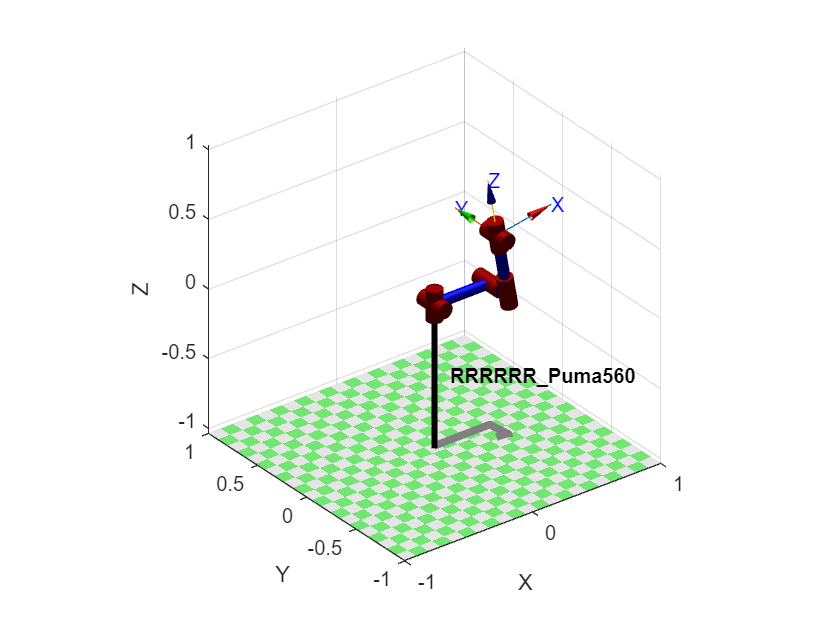

clc
clear
close all

% Puma560机器人
% theta         d               a               alpha
theta1 = 0.0;   d1 = 0.0;       a1 = 0.0;       alpha1 = pi/2;
theta2 = 0.0;   d2 = 0.0;       a2 = 0.4318;    alpha2 = 0;
theta3 = 0.0;   d3 = 0.15005;   a3 =  0.0203;   alpha3 = -pi/2;
theta4 = 0.0;   d4 = 0.4318;    a4 = 0.0;       alpha4 = pi/2;
theta5 = 0.0;   d5 = 0.0;       a5 = 0.0;       alpha5 = -pi/2;
theta6 = 0.0;   d6 = 0.0;       a6 = 0.0;       alpha6 = 0;

Lr1 = Link('revolute', 'd', d1, 'a', a1, 'alpha', alpha1, 'qlim',[-pi,pi]);
Lr2 = Link('revolute', 'd', d2, 'a', a2, 'alpha', alpha2, 'qlim',[-pi,pi]);
Lr3 = Link('revolute', 'd', d3, 'a', a3, 'alpha', alpha3, 'qlim',[-pi,pi]);
Lr4 = Link('revolute', 'd', d4, 'a', a4, 'alpha', alpha4, 'qlim',[-pi,pi]);
Lr5 = Link('revolute', 'd', d5, 'a', a5, 'alpha', alpha5, 'qlim',[-pi,pi]);
Lr6 = Link('revolute', 'd', d6, 'a', a6, 'alpha', alpha6, 'qlim',[-pi,pi]);
robot = SerialLink([Lr1 Lr2 Lr3 Lr4 Lr5 Lr6], 'name', 'RRRRRR\_Puma560');

% 指定关节变量
q1 = 0; q1 = q1*pi/180;     % 第一个关节的回转角度
q2 = 0; q2 = q2*pi/180;     % 第二个关节的回转角度
q3 = 10; q3 = q3*pi/180;     % 第三个关节的伸缩长度
q4 = 0; q4 = q4*pi/180;     % 第一个关节的回转角度
q5 = 0; q5 = q5*pi/180;     % 第二个关节的回转角度
q6 = 0; q6 = q6*pi/180;     % 第一个关节的回转角度
q = [q1, q2, q3, q4, q5, q6];
robot.plot(q);

% 命令行显示
%figure; robot.teach;

% 比较RTB中标准DH定义的Puma560机器人
mdl_puma560;
robot.display;

 
robot = 
 
RRRRRR\_Puma560:: 6 axis, RRRRRR, stdDH, slowRNE                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          0|     1.5708|          0|
|  2|         q2|          0|     0.4318|          0|          0|
|  3|         q3|    0.15005|     0.0203|    -1.5708|          0|
|  4|         q4|     0.4318|          0|     1.5708|          0|
|  5|         q5|          0|          0|    -1.5708|          0|
|  6|         q6|          0|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


p560.display;

 
p560 = 
 
Puma 560 [Unimation]:: 6 axis, RRRRRR, stdDH, slowRNE            
 - viscous friction; params of 8/95;                             
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          0|     1.5708|          0|
|  2|         q2|          0|     0.4318|          0|          0|
|  3|         q3|    0.15005|     0.0203|    -1.5708|          0|
|  4|         q4|     0.4318|          0|     1.5708|          0|
|  5|         q5|          0|          0|    -1.5708|          0|
|  6|         q6|          0|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


%figure; p560.teach;

clc
clear
close all

% UR5机器人
% theta         d               a               alpha               offset
theta1 = 0.0;   d1 = 0.089459;  a1 = 0.0;       alpha1 = pi/2;      ofs1 = 0;
theta2 = 0.0;   d2 = 0.0;       a2 = -0.425;    alpha2 = 0;         ofs2 = -pi/2;
theta3 = 0.0;   d3 = 0.0;       a3 = -0.39225;  alpha3 = 0;         ofs3 = 0;
theta4 = 0.0;   d4 = 0.10915;   a4 = 0.0;       alpha4 = -pi/2;     ofs4 = 0;
theta5 = 0.0;   d5 = 0.09465;   a5 = 0.0;       alpha5 = pi/2;      ofs5 = 0;
theta6 = 0.0;   d6 = 0.0823;    a6 = 0.0;       alpha6 = 0;         ofs6 = 0;

Lr1 = Link('revolute', 'd', d1, 'a', a1, 'alpha', alpha1, 'qlim',[-pi,pi], 'offset', ofs1);
Lr2 = Link('revolute', 'd', d2, 'a', a2, 'alpha', alpha2, 'qlim',[-pi,pi], 'offset', ofs2);
Lr3 = Link('revolute', 'd', d3, 'a', a3, 'alpha', alpha3, 'qlim',[-pi,pi], 'offset', ofs3);
Lr4 = Link('revolute', 'd', d4, 'a', a4, 'alpha', alpha4, 'qlim',[-pi,pi], 'offset', ofs4);
Lr5 = Link('revolute', 'd', d5, 'a', a5, 'alpha', alpha5, 'qlim',[-pi,pi], 'offset', ofs5);
Lr6 = Link('revolute', 'd', d6, 'a', a6, 'alpha', alpha6, 'qlim',[-pi,pi], 'offset', ofs6);
robot = SerialLink([Lr1 Lr2 Lr3 Lr4 Lr5 Lr6], 'name', 'RRRRRR\_UR5');

% 指定关节变量
q1 = 35; q1 = q1*pi/180;     % 第一个关节的回转角度
q2 = 35; q2 = q2*pi/180;     % 第二个关节的回转角度
q3 = 0; q3 = q3*pi/180;     % 第三个关节的伸缩长度
q4 = 0; q4 = q4*pi/180;     % 第一个关节的回转角度
q5 = 0; q5 = q5*pi/180;     % 第二个关节的回转角度
q6 = 0; q6 = q6*pi/180;     % 第一个关节的回转角度
q = [q1, q2, q3, q4, q5, q6];
robot.plot(q);
% 命令行显示
%figure; robot.teach;

% 比较RTB中标准DH定义的Puma560机器人
mdl_ur5;
robot.display;
ur5.display;
%figure; ur5.teach;

clc
clear
close all

% iiwa机器人
% theta         d               a               alpha               offset
theta1 = 0.0;   d1 = 0.0;       a1 = 0.0;       alpha1 = pi/2;      ofs1 = 0;
theta2 = 0.0;   d2 = 0.0;       a2 = 0.0;       alpha2 = -pi/2;     ofs2 = 0;
theta3 = 0.0;   d3 = 0.4;       a3 = 0.0;       alpha3 = -pi/2;     ofs3 = 0;
theta4 = 0.0;   d4 = 0.0;       a4 = 0.0;       alpha4 = pi/2;      ofs4 = 0;
theta5 = 0.0;   d5 = 0.39;      a5 = 0.0;       alpha5 = pi/2;      ofs5 = 0;
theta6 = 0.0;   d6 = 0.0;       a6 = 0.0;       alpha6 = -pi/2;     ofs6 = 0;
theta7 = 0.0;   d7 = 0.00;      a7 = 0.0;       alpha7 = 0;         ofs7 = 0;

Lr1 = Link('revolute', 'd', d1, 'a', a1, 'alpha', alpha1, 'qlim',[-pi,pi], 'offset', ofs1);
Lr2 = Link('revolute', 'd', d2, 'a', a2, 'alpha', alpha2, 'qlim',[-pi,pi], 'offset', ofs2);
Lr3 = Link('revolute', 'd', d3, 'a', a3, 'alpha', alpha3, 'qlim',[-pi,pi], 'offset', ofs3);
Lr4 = Link('revolute', 'd', d4, 'a', a4, 'alpha', alpha4, 'qlim',[-pi,pi], 'offset', ofs4);
Lr5 = Link('revolute', 'd', d5, 'a', a5, 'alpha', alpha5, 'qlim',[-pi,pi], 'offset', ofs5);
Lr6 = Link('revolute', 'd', d6, 'a', a6, 'alpha', alpha6, 'qlim',[-pi,pi], 'offset', ofs6);
Lr7 = Link('revolute', 'd', d7, 'a', a7, 'alpha', alpha7, 'qlim',[-pi,pi], 'offset', ofs7);
robot = SerialLink([Lr1 Lr2 Lr3 Lr4 Lr5 Lr6 Lr7], 'name', 'RRRRRR\_iiwa');

% 指定关节变量
q1 = 0; q1 = q1*pi/180;     % 第一个关节的回转角度
q2 = 0; q2 = q2*pi/180;     % 第二个关节的回转角度
q3 = 0; q3 = q3*pi/180;     % 第三个关节的伸缩长度
q4 = 0; q4 = q4*pi/180;     % 第一个关节的回转角度
q5 = 0; q5 = q5*pi/180;     % 第二个关节的回转角度
q6 = 0; q6 = q6*pi/180;     % 第一个关节的回转角度
q7 = 0; q7 = q6*pi/180;     % 第一个关节的回转角度
q = [q1, q2, q3, q4, q5, q6, q7];

view([20.0 70.0]); 
plotvol([-1.0 1.0 -1.0 1.0 -0.5 1.5]);
robot.plot(q);
% 命令行显示
%figure; robot.teach;


### 一.  D-H法则构建连杆

clc
close all

% 一个回转关节和一个移动关节组成的平面极坐标机器人
% d        theta               a           alpha
d1 = 1.2;  theta1 = 0.0;      a1 = 0.2;   alpha1 = pi/2;
d2 = 0.0;  theta2 = 0.0;      a2 = 0.6;   alpha2 = pi/2;

Lr = Link('d', d1, 'a', a1, 'alpha', alpha1, 'revolute')
Lp = Link('prismatic', 'theta', theta2, 'a', a2, 'alpha', alpha2, 'qlim',[0.5,2])
bot = SerialLink([Lr Lp], 'name', 'my robot')

% 用Fkine求正运动学，即获得坐标变换矩阵
Pz = [0, 0.5];
Ps = [pi/3, 1.5];
bot.plot(Pz);
T = bot.fkine(Ps)

% 根据D-H法则，手动计算的坐标变换矩阵
theta1 = Ps(1); d2 = Ps(2);
T01A = transl(0,0,d1)*trotz(theta1);
T01B = transl(a1,0,0)*trotx(alpha1);
T01 = T01A * T01B

T12A = transl(0,0,d2)*trotz(theta2);
T12B = transl(a2,0,0)*trotx(alpha2);
T02 = T01A*T12A
% T和T02是一致的。

% 示意D-H法则的坐标变化过程
T0 = transl(0,0,0); 
plotvol([-2.50 2.5 -2.5 2.5 -2.5 2.5]);
trplot(T0, 'frame', '0', 'color', 'r');
trplot(T01A, 'frame', '1', 'color', 'b');
trplot(T01, 'frame', '2', 'color', 'g');
trplot(T01*T12A, 'frame', '3', 'color', 'k');
trplot(T02, 'frame', '4', 'color', 'r');

### 二. D-H法则构建PUMA560

close all
% 角度换算
deg = pi/180;

% Revolute命令构建运动学及动力学参数
L(1) = Revolute('d', 0, 'a', 0, 'alpha', pi/2, ...
    'I', [0, 0.35, 0, 0, 0, 0], ...
    'r', [0, 0, 0], ...
    'm', 0, ...
    'Jm', 200e-6, ...
    'G', -62.6111, ...
    'B', 1.48e-3, ...
    'Tc', [0.395 -0.435], ...
    'qlim', [-160 160]*deg );

L(2) = Revolute('d', 0, 'a', 0.4318, 'alpha', 0, ...
    'I', [0.13, 0.524, 0.539, 0, 0, 0], ...
    'r', [-0.3638, 0.006, 0.2275], ...
    'm', 17.4, ...
    'Jm', 200e-6, ...
    'G', 107.815, ...
    'B', .817e-3, ...
    'Tc', [0.126 -0.071], ...
    'qlim', [-45 225]*deg );

L(3) = Revolute('d', 0.15005, 'a', 0.0203, 'alpha', -pi/2,  ...
    'I', [0.066, 0.086, 0.0125, 0, 0, 0], ...
    'r', [-0.0203, -0.0141, 0.070], ...
    'm', 4.8, ...
    'Jm', 200e-6, ...
    'G', -53.7063, ...
    'B', 1.38e-3, ...
    'Tc', [0.132, -0.105], ...
    'qlim', [-225 45]*deg );

L(4) = Revolute('d', 0.4318, 'a', 0, 'alpha', pi/2,  ...
    'I', [1.8e-3, 1.3e-3, 1.8e-3, 0, 0, 0], ...
    'r', [0, 0.019, 0], ...
    'm', 0.82, ...
    'Jm', 33e-6, ...
    'G', 76.0364, ...
    'B', 71.2e-6, ...
    'Tc', [11.2e-3, -16.9e-3], ...
    'qlim', [-110 170]*deg);

L(5) = Revolute('d', 0, 'a', 0, 'alpha', -pi/2,  ...
    'I', [0.3e-3, 0.4e-3, 0.3e-3, 0, 0, 0], ...
    'r', [0, 0, 0], ...
    'm', 0.34, ...
    'Jm', 33e-6, ...
    'G', 71.923, ...
    'B', 82.6e-6, ...
    'Tc', [9.26e-3, -14.5e-3], ...
    'qlim', [-100 100]*deg );


L(6) = Revolute('d', 0, 'a', 0, 'alpha', 0,  ...
    'I', [0.15e-3, 0.15e-3, 0.04e-3, 0, 0, 0], ...
    'r', [0, 0, 0.032], ...
    'm', 0.09, ...
    'Jm', 33e-6, ...
    'G', 76.686, ...
    'B', 36.7e-6, ...
    'Tc', [3.96e-3, -10.5e-3], ...
    'qlim', [-266 266]*deg );

% 构建PUMA560机器人
puma560_1 = SerialLink(L, 'name', 'Puma 560-1', ...
    'manufacturer', 'Unimation', 'ikine', 'puma', 'comment', 'viscous friction; params of 8/95');

% 指定显示模型
puma560_1.display()
%
% 典型位置姿变量
%
qz = [0 0 0 0 0 0];         % zero angles, L shaped pose
qr = [0 pi/2 -pi/2 0 0 0];  % ready pose, arm up
qs = [0 0 -pi/2 0 0 0];     % initial pose
qn=[0 pi/4 pi 0 pi/4  0];

% 正运动学求T矩阵
q = qz;
puma560_1.plot(q); T = puma560_1.fkine(q)
figure;puma560_1.teach()


### 三. 另一位形的D-H法则构建PUMA560

由于 $q_3$的零位选择不同，$Z_3$的方向可能相反，就会有不同的D-H定义，例如下面的例子：

因此，已经注意每个坐标系和关节角度零位的定义。

L(1) = Revolute('d', 0, 'a', 0, 'alpha', pi/2, ...
    'I', [0, 0.35, 0, 0, 0, 0], ...
    'r', [0, 0, 0], ...
    'm', 0, ...
    'Jm', 200e-6, ...
    'G', -62.6111, ...
    'B', 1.48e-3, ...
    'Tc', [0.395 -0.435], ...
    'qlim', [-160 160]*deg );

L(2) = Revolute('d', 0, 'a', 0.4318, 'alpha', 0, ...
    'I', [0.13, 0.524, 0.539, 0, 0, 0], ...
    'r', [-0.3638, 0.006, 0.2275], ...
    'm', 17.4, ...
    'Jm', 200e-6, ...
    'G', 107.815, ...
    'B', .817e-3, ...
    'Tc', [0.126 -0.071], ...
    'qlim', [-45 225]*deg );

L(3) = Revolute('d', 0.15005, 'a', 0.0203, 'alpha', pi/2,  ...
    'I', [0.066, 0.086, 0.0125, 0, 0, 0], ...
    'r', [-0.0203, -0.0141, 0.070], ...
    'm', 4.8, ...
    'Jm', 200e-6, ...
    'G', -53.7063, ...
    'B', 1.38e-3, ...
    'Tc', [0.132, -0.105], ...
    'qlim', [-225 45]*deg );

L(4) = Revolute('d', 0.4318, 'a', 0, 'alpha', -pi/2,  ...
    'I', [1.8e-3, 1.3e-3, 1.8e-3, 0, 0, 0], ...
    'r', [0, 0.019, 0], ...
    'm', 0.82, ...
    'Jm', 33e-6, ...
    'G', 76.0364, ...
    'B', 71.2e-6, ...
    'Tc', [11.2e-3, -16.9e-3], ...
    'qlim', [-110 170]*deg);

L(5) = Revolute('d', 0, 'a', 0, 'alpha', pi/2,  ...
    'I', [0.3e-3, 0.4e-3, 0.3e-3, 0, 0, 0], ...
    'r', [0, 0, 0], ...
    'm', 0.34, ...
    'Jm', 33e-6, ...
    'G', 71.923, ...
    'B', 82.6e-6, ...
    'Tc', [9.26e-3, -14.5e-3], ...
    'qlim', [-100 100]*deg );


L(6) = Revolute('d', 0, 'a', 0, 'alpha', 0,  ...
    'I', [0.15e-3, 0.15e-3, 0.04e-3, 0, 0, 0], ...
    'r', [0, 0, 0.032], ...
    'm', 0.09, ...
    'Jm', 33e-6, ...
    'G', 76.686, ...
    'B', 36.7e-6, ...
    'Tc', [3.96e-3, -10.5e-3], ...
    'qlim', [-266 266]*deg );

puma560_2 = SerialLink(L, 'name', 'Puma 560-2', ...
    'manufacturer', 'Unimation', 'ikine', 'puma', 'comment', 'viscous friction; params of 8/95');

% 指定显示模型
puma560_2.display()
puma560_1.display()

q = qz; q(3)=pi/2;
puma560_2.plot(q); T = puma560_2.fkine(q)
puma560_2.teach()